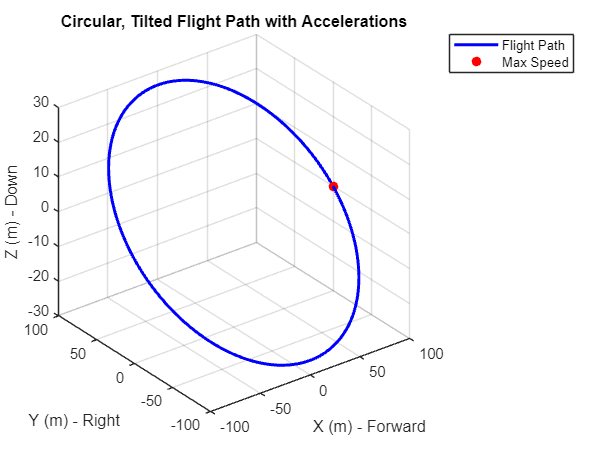

% Simulation Parameters
turns = 20;                   % Number of turns
t_total = 30;                  % Total time for the simulation in seconds
radius = 100;                  % Radius of the circular trajectory (meters)
tilt_angle = 15;               % Tilt angle of the circle (degrees)
initial_speed_kmh = 50;        % Initial speed in km/h
final_speed_kmh = 900;         % Final speed in km/h
omega_z = initial_speed_kmh / radius; % Angular velocity based on initial speed

% Convert speeds to meters per second
initial_speed = initial_speed_kmh * 1000 / 3600; % in m/s
final_speed = final_speed_kmh * 1000 / 3600; % in m/s

% Time vector (duration for each turn is based on angular velocity)
t = linspace(0, turns * 2 * pi / omega_z, 3000); % Simulate for 20 turns

% Compute the trajectory in the body frame
theta = omega_z * t; % Angle around the circle
x = radius * cos(theta); % X-coordinates (forward motion)
y = radius * sin(theta); % Y-coordinates (lateral motion)
z = radius * sin(deg2rad(tilt_angle)) * sin(theta); % Z-coordinates (tilt effect)

% Speed increment needed to reach the final speed after 20 turns
total_speed_increase = final_speed - initial_speed; % Speed to increase in m/s
acceleration_needed = total_speed_increase / (turns / 3); % Acceleration for 1/3 of each circle

% Initialize velocity components
vx = initial_speed * cos(theta); % Initial velocity in x-direction
vy = initial_speed * sin(theta); % Initial velocity in y-direction
vz = zeros(size(t)); % No initial vertical velocity

% Apply acceleration only in 1/3 of the circle
acceleration = zeros(size(t)); % Acceleration vector
for i = 1:length(t)
    if mod(theta(i), 2*pi) < (2*pi/3)  % First third of the circle
        acceleration(i) = acceleration_needed; % Apply acceleration
    end
end

% Update velocities based on acceleration
vx = vx + cumsum(acceleration .* cos(theta)); % Apply acceleration to x-direction
vy = vy + cumsum(acceleration .* sin(theta)); % Apply acceleration to y-direction

% Recompute speed after applying acceleration
speed_magnitude = sqrt(vx.^2 + vy.^2 + vz.^2); % Speed at each time point

% Maximum speed and corresponding time
[max_speed, idx_max_speed] = max(speed_magnitude);
t_max_speed = t(idx_max_speed); % Time at maximum speed

% Acceleration in each direction (with added acceleration)
ax = -radius * omega_z^2 * cos(theta) + acceleration .* cos(theta); % Forward acceleration
ay = -radius * omega_z^2 * sin(theta) + acceleration .* sin(theta); % Lateral acceleration
az = -radius * omega_z^2 * sin(deg2rad(tilt_angle)) * sin(theta); % Vertical acceleration

% Add gravity effect to accelerations in z-direction
gravity = 9.81; % Gravity constant (m/s^2)
az = az - gravity; % Subtract gravity from vertical acceleration

% Angular rates (roll, pitch, yaw)
omega_x = zeros(size(t)); % No roll
omega_y = zeros(size(t)); % No pitch
omega_z = repmat(omega_z, size(t)); % Constant yaw rate

% Angular accelerations
alpha_x = zeros(size(t)); % No roll acceleration
alpha_y = zeros(size(t)); % No pitch acceleration
alpha_z = zeros(size(t)); % No yaw acceleration

% 3D Flight Path Plot
figure;
plot3(x, y, z, 'b', 'LineWidth', 2);
hold on;
% Mark the maximum speed point on the 3D plot
plot3(x(idx_max_speed), y(idx_max_speed), z(idx_max_speed), 'ro', 'MarkerFaceColor', 'r');
grid on;
xlabel('X (m) - Forward');
ylabel('Y (m) - Right');
zlabel('Z (m) - Down');
title('Circular, Tilted Flight Path with Accelerations');
legend('Flight Path', 'Max Speed');
view(3);

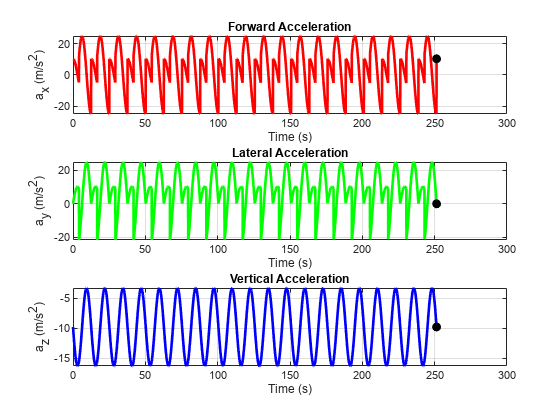


% Plot accelerations over time
figure;
subplot(3, 1, 1);
plot(t, ax, 'r', 'LineWidth', 2);
hold on;
% Mark the maximum speed on the acceleration plot
plot(t_max_speed, ax(idx_max_speed), 'ko', 'MarkerFaceColor', 'k');
xlabel('Time (s)');
ylabel('a_x (m/s^2)');
title('Forward Acceleration');
grid on;

subplot(3, 1, 2);
plot(t, ay, 'g', 'LineWidth', 2);
hold on;
% Mark the maximum speed on the acceleration plot
plot(t_max_speed, ay(idx_max_speed), 'ko', 'MarkerFaceColor', 'k');
xlabel('Time (s)');
ylabel('a_y (m/s^2)');
title('Lateral Acceleration');
grid on;

subplot(3, 1, 3);
plot(t, az, 'b', 'LineWidth', 2);
hold on;
% Mark the maximum speed on the acceleration plot
plot(t_max_speed, az(idx_max_speed), 'ko', 'MarkerFaceColor', 'k');
xlabel('Time (s)');
ylabel('a_z (m/s^2)');
title('Vertical Acceleration');
grid on;

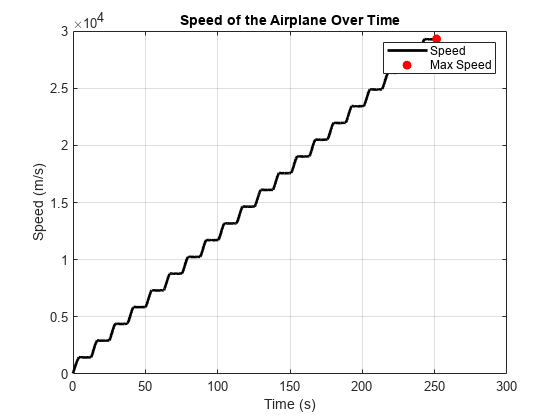


% Plot Speed over time
figure;
plot(t, speed_magnitude, 'k', 'LineWidth', 2);
hold on;
% Mark the maximum speed on the speed plot
plot(t_max_speed, max_speed, 'ro', 'MarkerFaceColor', 'r');
xlabel('Time (s)');
ylabel('Speed (m/s)');
title('Speed of the Airplane Over Time');
grid on;
legend('Speed', 'Max Speed');

% Calculate total acceleration based on speed and radius
centripetal_accel = (vx.^2 + vy.^2) / radius;  % Centripetal acceleration

% The total acceleration is the sum of centripetal acceleration and applied acceleration
total_acceleration = sqrt(ax.^2 + ay.^2 + az.^2 + centripetal_accel.^2);

% Calculate the g-force (total acceleration divided by gravity)
g_force = total_acceleration / gravity;

% You can also find the maximum g-force and corresponding time if needed
[max_g, idx_max_g] = max(g_force); 
t_max_g = t(idx_max_g); % Time at maximum g-force


max_g = 8.7573e+05

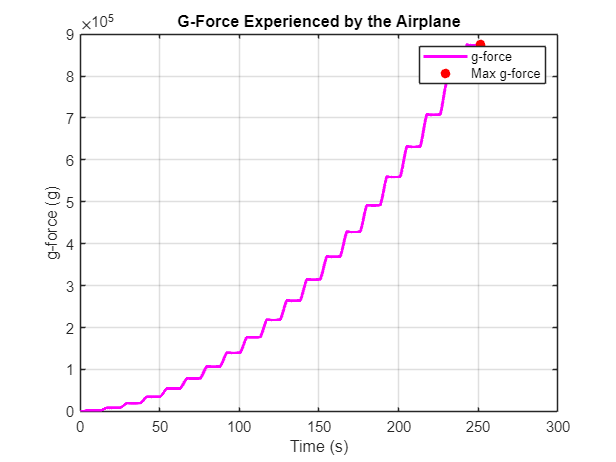

% Optionally, plot the g-force over time
figure;
plot(t, g_force, 'm', 'LineWidth', 2);
hold on;
plot(t_max_g, max_g, 'ro', 'MarkerFaceColor', 'r');
xlabel('Time (s)');
ylabel('g-force (g)');
title('G-Force Experienced by the Airplane');
grid on;
legend('g-force', 'Max g-force');